# HomeWork n.2 2023/24

## Corso di Calcolo Numerico  (CdS Informatica) - proff. G. Giunta - A. Galletti

**(scadenza:  16 giugno 2024, ore 23:59)**

**Fontanella Vincenzo 0124002767**

format long

1.**  Interpolazione**

Definire un dominio $[a,b]$ ed una funzione composta $f(x)$ in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc.). Per stabilire un intervallo nel quale $f$sia definita e non prensenti punti di discontinuità, utilizzare eventualmente la function MATLAB *ezplot *per osservarne il grafico. 

Definire quindi un insieme di $m$ punti $P=\{(x_i,y_i)\}_{i=1}^m$ con $8 \leq m \leq 19, m \in \mathbb{N}$. Le ascisse di $P$ sono linearmente distribuite in $[a,b]$, le ordinate sono i corrispondenti valori assunti dalla valutazione di $f(x)$.

        1.1. Definire un insieme $\mathcal{F}$di funzioni modello polinomiali. Scegliere un'opportuna base così da determinare il polinomio $p$  $\in$ $\mathcal{F}$ che interpola $f$ nei nodi $x_i$. Costruire il relativo sistema lineare $Ba=y$ e risolverlo (non usare il comando backslash di MATLAB).  Calcolare inoltre l'indice di condizionamento della matrice $B$.

        1.2. Valutare il polinomio $p$ su una griglia di $N$ punti di valutazione distribuiti casualmente in $[a,b]$. Fissare $N\,\,( 314 \leq N \leq 341)$. Calcolare l'errore di interpolazione della funzione interpolante scelta al punto precedente.

        1.3. Interpolare i punti $P$ mediante una spline $s$ di terzo grado di tipo *not-a-knot*.  Valutare l'interpolante ottenuto sulla griglia di $N$ punti di valutazione del punto 1.2.

        1.4. Fissare un valore $n\,\,( 7 \leq n \leq 17)$ e definire un nuovo insieme di punti $Q = \{(x_j, y_j)\}_{j=1}^n$ le cui ascisse sono i nodi di Chebyshev in $[a,b]$ e le cui ordinate sono i valori corrispondenti assunti da $f(x)$. Costruire il polinomio interpolante i punti $Q$ e valutarlo sulla griglia di valutazione generata al punto 1.2.

        1.5. Infine, mostrare graficamente l'andamento dell'errore di interpolazione. Confrontare numericamente l'errore con quello ottenuto al punto 1.2.

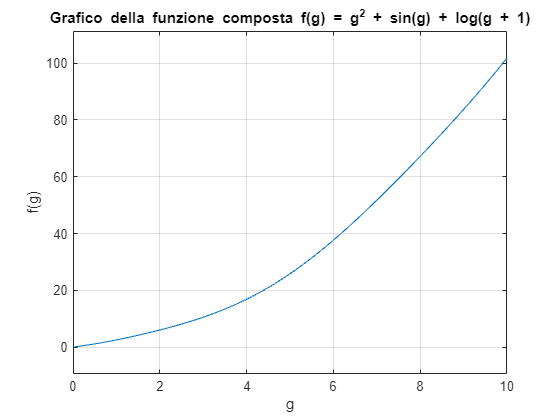

% 1 Interpolazione polinomiale
f = @(g) g.^2 + sin(g) + log(g + 1);
a = 0;
b = 10;

% Grafico della funzione
figure;
ezplot(f, [a, b]);
title('Grafico della funzione composta f(g) = g^2 + sin(g) + log(g + 1)');
xlabel('g');
ylabel('f(g)');
grid on;


% Nodi di interpolazione (8<=m<=19 punti),linearmente distribuite tramite
% linspace
x = linspace(a, b, 8)'; 
y = f(x);

% Matrice di Vandermonde e sistema lineare
B = vander(x);
B = fliplr(B); % Meglio di fare (end:-1:1), in quanto Lagrange lo impone in ordine inverso

[L, U, P] = lu(B);
b_vec = P * y;

opts1.LT = true; 
y_ = linsolve(L, b_vec, opts1);

opts2.UT = true;
a_coeff = linsolve(U, y_, opts2); %%Nota: la definizione di LU=Vb è lunga e sta nell'argomento 4 ultima
%%lezione, Questa è la definizione di backslash

cond_B = cond(B); %%Abbiamo letteralmente parlato del condizionamento di una matrice per un attimo in una esercitazione, la formula è anche online


% Visualizzazione dei coefficienti e del condizionamento
disp('Coefficienti del polinomio interpolante:');

Coefficienti del polinomio interpolante:


disp(a_coeff');

                   0   1.131292126821074   2.071844585838870  -0.976448529505300   0.261572691890037  -0.030624280013144   0.001594677793287  -0.000028817168706




disp('Indice di condizionamento della matrice di Vandermonde:');

Indice di condizionamento della matrice di Vandermonde:


disp(cond_B);

     2.982295695651197e+08



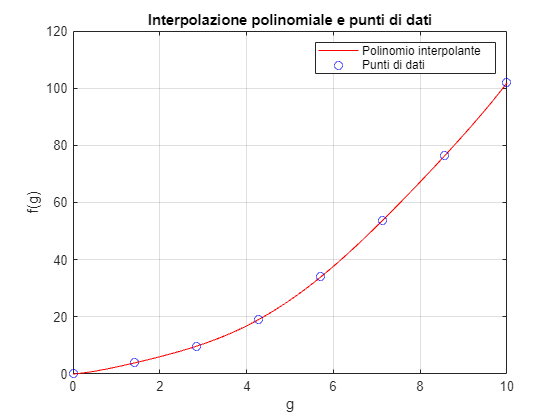


% Verifica dei punti interpolati
x_check = linspace(a, b, 100);
y_check = polyval(flipud(a_coeff), x_check); %% Nota: le funzioni di von der monde erano invertite, quindi flipud le ri-inverte, altrimenti l'interpolazione era piatta e c_check è come un xx


figure;
plot(x_check, y_check, 'r-', x, y, 'bo');
title('Interpolazione polinomiale e punti di dati');
xlabel('g');
ylabel('f(g)');
legend('Polinomio interpolante', 'Punti di dati');
grid on; %%la funzione descrive un'approssimazione tramite von der monde della funzione non lineare f tramite le a coefficienti



% 1.2 Calcolare l'errore di interpolazione
num_points = 320; %%314<n<341
x_rand = a + (b - a) * rand(num_points, 1); %% su 1 riga, 320 punti tra 0 e 1   , distribuiti tra a e b sulla griglia da valutare


% Calcolo dei valori della funzione originale e del polinomio interpolante
y_true = f(x_rand);
y_interp = polyval(flipud(a_coeff), x_rand);  %%flipud ancora inverte l'ordine

% Calcolo dello scarto di interpolazione
interp_error = y_true - y_interp;

% Calcolo della norma (2) dell'errore
error_norm = norm(interp_error);

% Visualizzazione dell'errore di interpolazione
disp('Errore di interpolazione (norma):');

Errore di interpolazione (norma):


disp(error_norm);

   0.877785167463154



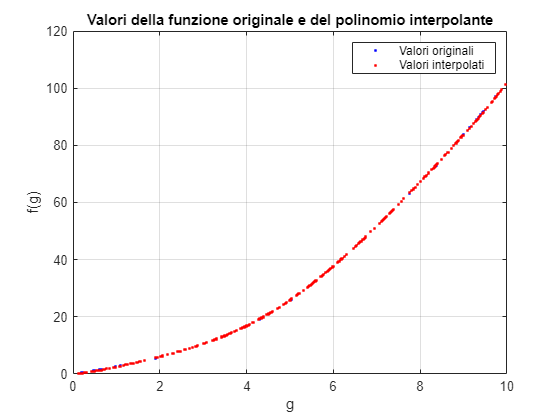


figure;
plot(x_rand, y_true, 'b.', x_rand, y_interp, 'r.'); %Interpolazione come simulazione lagrangiana della funzione originale in rosso e i calcoli di forza bruta in blu
title('Valori della funzione originale e del polinomio interpolante');
xlabel('g');
ylabel('f(g)');
legend('Valori originali', 'Valori interpolati');
grid on;


% 1.3 Interpolazione con spline di terzo grado
% Interpolazione mediante spline di terzo grado
spline_interp = spline(x, y);

% Calcolo dei valori della spline interpolante nei punti casuali
x_rand_double = double(x_rand);
y_spline_interp = ppval(spline_interp, x_rand_double); %piecewise polyval

% Calcolo dello scarto di interpolazione della spline (vettore)
spline_interp_error = y_true - y_spline_interp;

% Calcolo della norma dell'errore della spline (Norma dell'errore dei
% vettori)
spline_error_norm = norm(spline_interp_error);

% Visualizzazione dell'errore di interpolazione della spline
disp('Errore di interpolazione della spline (norma):');

Errore di interpolazione della spline (norma):


disp(spline_error_norm);

   0.648522007315502



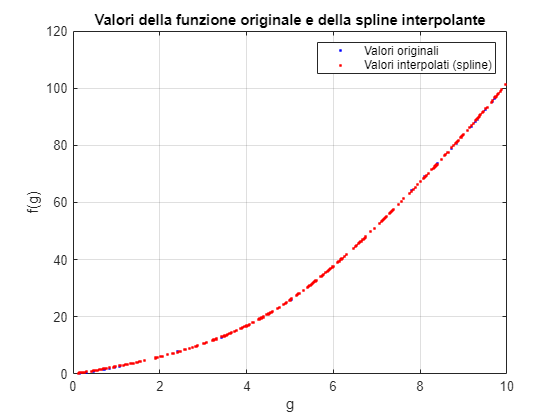


figure;
plot(x_rand, y_true, 'b.', x_rand, y_spline_interp, 'r.');
title('Valori della funzione originale e della spline interpolante'); %Metodo spline con le almeno 6 condizioni rispetto al punto 1.2
xlabel('g');
ylabel('f(g)');
legend('Valori originali', 'Valori interpolati (spline)');
grid on;

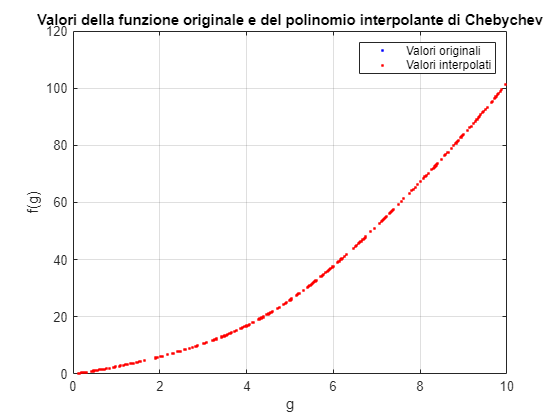

%%Debug Time
% 1.4 Interpolazione con nodi di Chebyshev
n = 12; %7<n<17  Nota: possiamo usare randi per rendere la scelta diversa ogni volta, ma meglio fissare per sicurezza
cheb_nodes = (a + b) / 2 + ((b - a) / 2) * cos((0:(n-1)) * pi / (n-1)); %Metodo di chebichev studiato
Q = f(cheb_nodes); % Valori corrispondenti assunti da f(x) nei nodi di Chebychev


% Costruzione del polinomio interpolante trovando i coefficienti che
% tangeranno con la sequenza di polyfit
coeff_cheb = polyfit(cheb_nodes, Q, n-1);

% Valutazione del polinomio interpolante sulla griglia di valutazione
% generata al punto 1.2 effettivamente costruendo la simulazione a, a2x,
% a3x^2...
y_cheb_interp = polyval(coeff_cheb, x_rand);

% Visualizzazione dei punti di valutazione e del polinomio interpolante più
% stabile dell'originale sul lungo termine
figure;
plot(x_rand, y_true, 'b.', x_rand, y_cheb_interp, 'r.');
title('Valori della funzione originale e del polinomio interpolante di Chebychev');
xlabel('g');
ylabel('f(g)');
legend('Valori originali', 'Valori interpolati');
grid on;

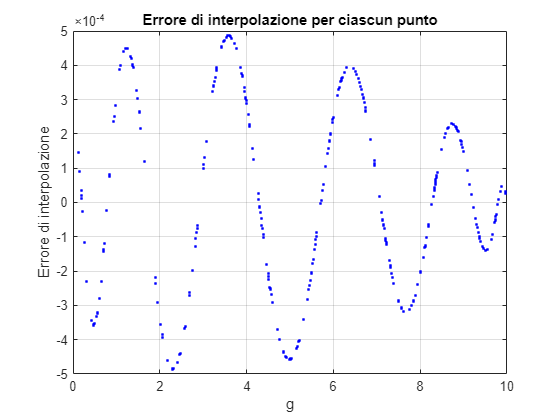


% 1.5 Visualizzare l'andamento dell'errore di interpolazione
% Calcolo dell'errore di interpolazione per ciascun punto sulla griglia di
% valutazione, L'errore è più alto verso il centro con la versione di
% chebichev, ma la richiesta del punto 1.2 è che i valori siano "distribuiti casualmente", quindi
% devi fdarti delle leggi della probabilità. Ciò che è sicuro è che
% chebicev è ideale per un numero maggiore di punti sul lungo termine, che
% aumtenta l'accuratezza all'aumentare di k (0:n-1)
interp_error_pointwise = y_true - y_cheb_interp;

figure;
plot(x_rand, interp_error_pointwise, 'b.');
title('Errore di interpolazione per ciascun punto');
xlabel('g');
ylabel('Errore di interpolazione');
grid on;

% Calcolo della norma dell'errore di interpolazione per trovare la
% dimensione del vettore
interp_error_norm = norm(interp_error_pointwise);

disp('Errore di interpolazione (norma) al punto 1.5:'); % Ci sono abbastanza punti perché chebichev sia più preciso

Errore di interpolazione (norma) al punto 1.5:


disp(interp_error_norm);

   0.004920297232522



disp('Errore di interpolazione (norma) al punto 1.2:');

Errore di interpolazione (norma) al punto 1.2:


disp(error_norm);

   0.877785167463154



 2.** Interpolazione di curve parametriche**

  Si considerino le seguenti curve parametriche:

         1. $\begin{cases}
x = \frac{a \cdot \cos(\theta)}{1 + \sin^2(\theta)} \\
y = \frac{a \cdot \sin(\theta) \cdot \cos(\theta)}{1 + \sin^2(\theta)}
\end{cases}
\quad 0 \leq \theta \leq 2\pi$

         2. $\begin{cases}
x = \sin(\theta) \left(e^{\cos(\theta)} - 2 \cos(4\theta) - \sin^5\left(\frac{\theta}{12}\right)\right) \\
y = \cos(\theta) \left(e^{\cos(\theta)} - 2 \cos(4\theta) - \sin^5\left(\frac{\theta}{12}\right)\right)
\end{cases}
\quad 0 \leq \theta \leq 12\pi$

         3. $\begin{cases}
x = a \cdot \theta \cdot \cos(\theta) \\
y = a \cdot \theta \cdot \sin(\theta)
\end{cases}
\quad 0 \leq \theta \leq 4\pi$

Scegliere una di tali curve e campionarla in $n$ punti $P=\{(x_i,y_i)\}_{i=1}^n$, corrispondenti a $n$ punti $t_i$ equispaziati nell'intervallo $[a,b]$ in cui varia il parametro $t$ (fissare $20<n<30$). 

     2.1. costruire due spline parametriche $p_x$ e $p_y$ che interpolino rispettivamente i punti $(t_i,x_i)$ e i punti $(t_i, y_i)$  ($i = 1,\ldots, n$);

    2.2.  valutare le spline parametriche su una griglia fitta $\Gamma$ opportuna e mostrare il grafico della curva parametrica interpolata.

    2.3.  Ripetere i punti 2.1 e 2.2 su un insieme di $m=50$ punti $S = \{(x_j,y_j)\}_{j=1}^m$ le cui ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando `ginput` usato su una immagine a propria scelta oppurtunamente caricata (usare `imread). `Le coordinate devono essere estese aggiungendo in coda un punto fittizio coincidente col primo punto, in modo tale che `x` e `y` siano i vettori delle coordinate dei vertici di un poligono (chiuso). 

       2.4. Ricostruire inoltre la curva parametrica passante per i punti definiti al punto 2.3 mediante le cubiche di Hermite (non spline cubiche). Calcolare la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite su $\Gamma$.

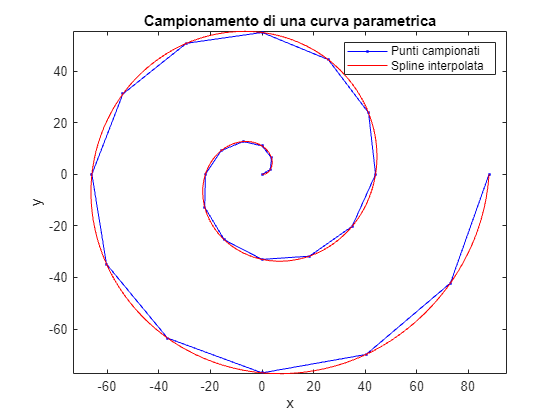

% Definizione del numero di punti n
n = 25; % 20 < n < 30

% Definizione del vettore dei parametri t in n punti tra i predefiniti a e b equispaziati
t = linspace(0, 4*pi, n);

% Campionamento della curva parametrica
x = 7 * t .* cos(t); %alpha=7. Nota: La figura 3 era la figura più facile non solo da scrivere, ma anche da immaginare.
y = 7 * t .* sin(t);

% Plot della curva
figure;
plot(x, y, 'b.-'); % Plot dei punti con linea. Nota: è giusto una verifica, in quanto non richiesta nel punto 2, ma questo è il metodo di spline lineare
axis equal; % Imposta l'asse x e l'asse y con la stessa scala
xlabel('x');
ylabel('y');
title('Campionamento di una curva parametrica');

% 2.1. Costruzione delle spline parametriche p_x e p_y che interpolano rispettivamente i punti x e i punti y
tt = linspace(t(1), t(end), 250);
p_x = spline(t, x, tt);
p_y = spline(t, y, tt);

% 2.2. Valutazione delle spline parametriche su una griglia fitta opportuna e visualizzazione del grafico della curva parametrica interpolata
hold on;
plot(p_x, p_y, 'r-'); % Plot delle spline con linea rossa
legend('Punti campionati', 'Spline interpolata');
hold off;

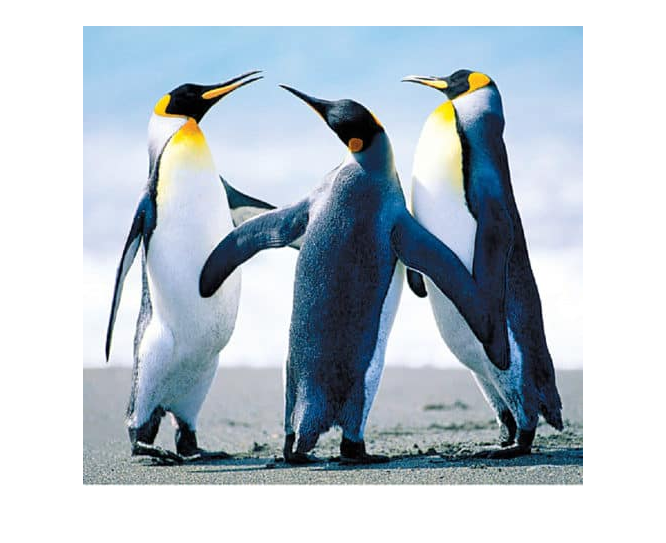


% 2.3. Ripetizione dei punti 2.1 e 2.2 su un insieme di m=50 punti le cui
% ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando ginput
% su una immagine caricata (Usare il metodo intuibile del plot e delle
% spline ma con punti fissi invece di funzioni come x e y)
% Caricamento dell'immagine NON TANTO visto in classe
img = imread('3-8-500x460.jpg'); % Sostituisci la mia immagine con il nome dell'immagine

% Visualizzazione dell'immagine
figure;
imshow(img);
title('Seleziona 50 punti con il mouse (5 se in fase di test)');

% Utilizzo di ginput per ottenere 50 punti dall'immagine (Visto in classe
% durante l'esercitazione col cuore, ma con una funzione precisa)
% Proviamo con una stella, diminuendo a 5 gli input
[y,x] = ginput(50);

% Estensione delle coordinate per chiudere il poligono, come visto
% nell'ultima nota della lezione del cuore
x = [x; x(1)];
y = [y; y(1)];

% Visualizzazione dei punti e del poligono
figure;
imshow(img);

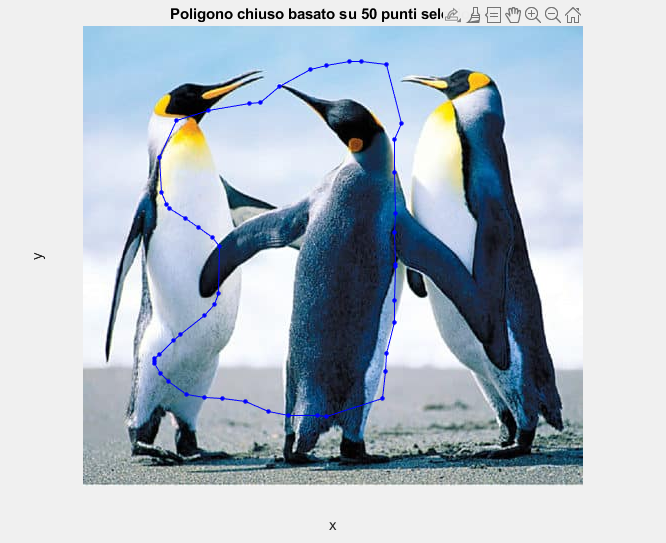

hold on;
%2.3.1
plot(x, y, 'b.-', 'MarkerSize', 10); % Disegna i punti e il poligono tramite metodo 2.1 (verifica)
xlabel('x');
ylabel('y');
title('Poligono chiuso basato su 50 punti selezionati');
hold off;

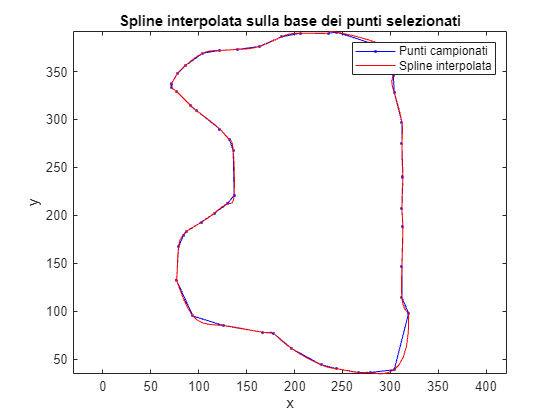

%2.3.2
% Costruzione delle spline parametriche p_x e p_y che interpolano
% rispettivamente i punti x e i punti y tramite metodo nelle slides (spline
% cubica interpolante)
t = linspace(1, length(x), length(x)); % Creazione di un vettore t di parametri 
tt = linspace(t(1), t(end), 250); % Griglia fitta di valutazione
p_x = spline(t, x, tt);
p_y = spline(t, y, tt);

% Visualizzazione del grafico della curva parametrica interpolata
figure;
plot(x, y, 'b.-'); % Plot dei punti con linea (2.1)
hold on;
plot(p_x, p_y, 'r-'); % Plot delle spline con linea rossa (2.2)
axis equal;
xlabel('x');
ylabel('y');
title('Spline interpolata sulla base dei punti selezionati');
legend('Punti campionati', 'Spline interpolata');
hold off;

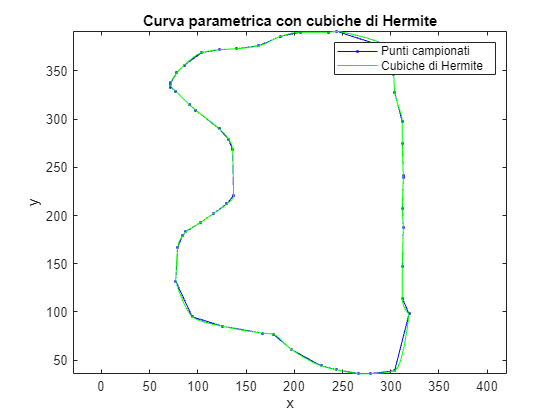

% 2.4. Ricostruzione della curva parametrica passante per i punti definiti al punto 2.3 mediante le cubiche di Hermite (non spline cubiche)
tg = linspace(1, length(x), length(x)); % Creazione di un vettore t di parametri (verifica)
ttg = linspace(tg(1), tg(end), 250); % Griglia fitta di valutazione
p_xg = pchip(tg, x, ttg);
p_yg = pchip(tg, y, ttg);

% Visualizzazione del grafico della curva parametrica interpolata con cubiche di Hermite
figure;
plot(x, y, 'b.-'); % Plot dei punti con linea
hold on;
plot(p_xg, p_yg, 'g-'); % Plot delle cubiche di Hermite con linea verde shape preserving
axis equal;
xlabel('x');
ylabel('y');
title('Curva parametrica con cubiche di Hermite');
legend('Punti campionati', 'Cubiche di Hermite');
hold off;


% Calcolo della norma infinito del vettore contenente le ordinate della
% cubica di Hermite (Lezione 4.3)
norma_infinito = norm(p_yg, Inf);
disp(['La norma infinito delle ordinate della cubica di Hermite è: ', num2str(norma_infinito)]); %num2str=>:( Odio il debug

La norma infinito delle ordinate della cubica di Hermite è: 390.9933


3. **Approssimazione**

Generare un insieme di punti $C=\{(t_i,y_i)\}_{i=1}^n$ le cui ascisse $t_1,t_2,\ldots,t_n$ appartengono all'intervallo [3,4] e i valori  $y_i$  sono i valori perturbati della funzione $f(t)=t^3-2t+17$ nei punti $t_i$, dove la perturbazione si intende introdotta aggiungendo un errore casuale tra 0 e 1 ad ogni valore $y_i$. Scegliere inoltre $11 \leq n \leq 17$.

         3.1 Costruire e valutare, su una griglia fitta di almeno 73 punti, utilizzando i metodi studiati, la cubica dei minimi quadrati approssimante i dati.

         3.2. Mostrare graficamente sia il polinomio di terzo grado approssimante che i punti approssimati ed evidenziare sul grafico gli scostamenti.

         3.3. Ripetere il punto precedente variando il grado del polinomio approssimante nell'intervallo tra 1 e 5. Mostrare tutte le curve approssimanti ottenute sullo stesso grafico.

         3.4. Valutare il residuo in norma due per ognuna delle curve precedentemente ottenute.

% Numero di punti
num_points = 15 % 11<n<17;

num_points =     15



% Genera ascisse nell'intervallo [3, 4]
x = 3 + (4-3) * rand(1, num_points);  % una riga di 15 punti tra 0 e 1 * deviazione standard+origine

% Funzione f = t^3 - 2t + 17
f = @(t) t.^3 - 2*t + 17;

% Calcola i valori della funzione nei punti x
y = f(x);

% Aggiungi un errore casuale tra 0 e 1 ad ogni valore y(i)
y_perturbed = y + rand(1, num_points);

% Visualizza i risultati come risultati su cui lavorare
C = [x' y_perturbed'];
disp('Punti (x, y):');

Punti (x, y):


disp(C);

   3.143156022083576  42.283256175658416
   3.559370572403004  55.146395762882996
   3.004579623947324  39.053237315662670
   3.766681998621487  63.498401391289200
   3.848709226458282  66.752462996640077
   3.916821270253738  70.198146286202160
   3.986968274783658  73.058490157526819
   3.505133101798823  53.505597793728015
   3.271421624417515  46.308260864126716
   3.100750511921236  41.143764976137582
   3.507848830829537  53.702281264164796
   3.585609125701879  56.607563756099054
   3.762887095910741  63.121335581444988
   3.082962649110544  40.375873059700581
   3.661596193082714  59.347800977736199



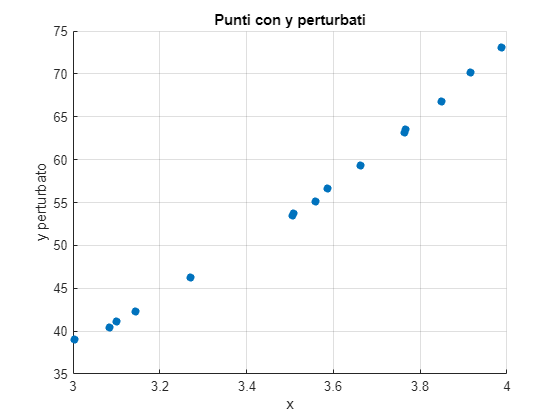


% Plot dei punti perturbati
figure;
scatter(x, y_perturbed, 'filled'); %scatter come plot ma non allinea i punti per evitare confusione con l'interpolazione
title('Punti con y perturbati');
xlabel('x');
ylabel('y perturbato');
grid on;

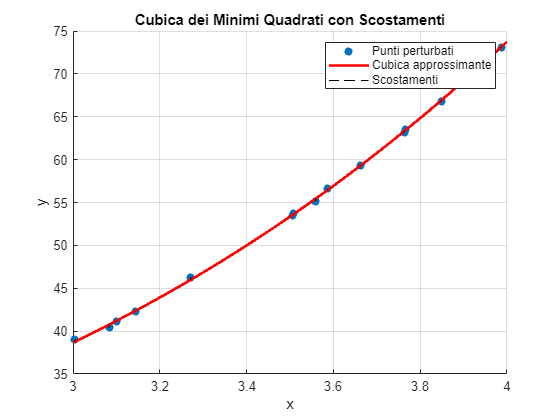

%3.1 Costruzione del polinomio cubico dei minimi quadrati
p = polyfit(x, y_perturbed, 3);  %a(1), a(2)x..., costruendo una matrice di von der monde e triangolandola LUV in modo non tradizionale attravarso le almeno 6 condizioni per creare una matrice B'*B*a=B'*y. Il Risultato è un polinomio di grado 3 con un'approssimazione di massima accuratezza 

% Generazione di una griglia fitta di 73 punti nell'intervallo [3, 4]
x_fine = linspace(3, 4, 73);

% Valutazione del polinomio cubico sui punti della griglia valutandola per
% 73 punti tra 3 e 4
y_fine = polyval(p, x_fine);  

% Valutazione del polinomio cubico sui punti originali (3.2) (Come sarebbe
% la funzione corretta se non delimitata dal suo grado che non la fa
% interpolare)
y_fit = polyval(p, x);

% Plot della cubica dei minimi quadrati e degli scostamenti
figure;
hold on;
scatter(x, y_perturbed, 'filled'); % Punti perturbati
plot(x_fine, y_fine, 'r-', 'LineWidth', 2); % Polinomio cubico

% Aggiunta delle linee di scostamento che determinano la distanza tra i
% punti originali nelle x d'origine e la distanza tra le y che è lo scarto
% tra la soluzione perfetta (interpolazione) e adattamento (cubica
% approssimante). Nota, l'f(x) non fa notare bene gli scostamenti, ma se si
% ingrandisce...
for i = 1:num_points
    plot([x(i), x(i)], [y_perturbed(i), y_fit(i)], 'k--');
end

title('Cubica dei Minimi Quadrati con Scostamenti');
xlabel('x');
ylabel('y');
legend('Punti perturbati', 'Cubica approssimante', 'Scostamenti');
grid on;
hold off;

%3.3 Ripetere il punto precedente variando il grado del polinomio approssimante nell'intervallo tra 1 e 5. Mostrare tutte le curve approssimanti ottenute sullo stesso grafico.
% Numero di punti
num_points = 15; % 11<n<17

% Genera ascisse nell'intervallo [3, 4]
x = 3 + (4-3) * rand(1, num_points);

% Funzione f = t^3 - 2*t + 17
f = @(t) t.^3 - 2*t + 17;

% Calcola i valori della funzione nei punti x
y = f(x);

% Aggiungi un errore casuale tra 0 e 1 ad ogni valore y(i)
y_perturbed = y + rand(1, num_points);

% Visualizza i risultati
C = [x' y_perturbed'];
disp('Punti (x, y):');

Punti (x, y):


disp(C);

   3.866887054672508  67.384629937890551
   3.406776760215226  50.150791676443333
   3.112615141025047  41.050153519301986
   3.443845836726958  51.451642225253160
   3.300184401213900  47.049063149411843
   3.401386853814493  49.792915376313729
   3.833363563453134  66.448379313688747
   3.403628662773607  49.696808629455660
   3.390175938130607  49.577816561302640
   3.360448893378944  48.230757847542748
   3.140255359269444  41.906864008432542
   3.260130194112440  45.131167299101982
   3.086815100865834  40.428043261697702
   3.429397337085805  50.616029311027468
   3.257282784769860  45.312926188051414



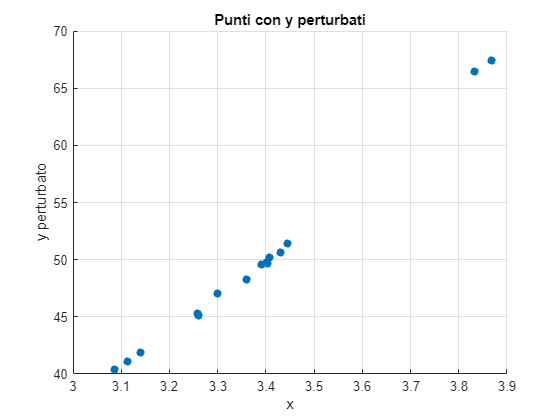


% Plot dei punti perturbati
figure;
scatter(x, y_perturbed, 'filled');
title('Punti con y perturbati');
xlabel('x');
ylabel('y perturbato');
grid on;

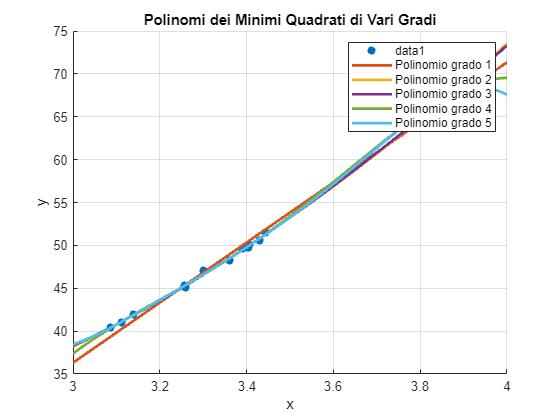

% E fin qui...3.1
% Generazione di una griglia fitta di 73 punti nell'intervallo [3, 4]
x_fine = linspace(3, 4, 73);

% Preparazione del grafico per le curve approssimanti
figure;
scatter(x, y_perturbed, 'filled'); % Punti perturbati
hold on; % 3.2 modificato:

% Inizializzazione dell'array per i residui
residui = zeros(1, 5); % Preparazione dei nodi per le norme (3.4)

% Ciclo sui gradi del polinomio da 1 a 5, applicando il solito metodo di
% prima, ma volta per volta (notare l'hold on scritto qui sopra)
for degree = 1:5
    % Costruzione del polinomio di grado 'degree' dei minimi quadrati
    p = polyfit(x, y_perturbed, degree);
    
    % Valutazione del polinomio sui punti della griglia di minimo 73
    y_fine = polyval(p, x_fine);
    
    % Valutazione del polinomio sui punti originali (Come nel punto 3.2 ma
    % per ogni approssimazione)(3.3)
    y_fit = polyval(p, x);
    
    % Calcolo del residuo in norma euclidea (y nell'approssimazione e
    % nell'originale come vettore su cui fare radice su somma di quadrati)
    residuo = norm(y_perturbed - y_fit, 2);
    residui(degree) = residuo;
    
    % Plot della curva approssimante
    plot(x_fine, y_fine, 'DisplayName', sprintf('Polinomio grado %d', degree), 'LineWidth', 2);%Nota: qui legend è un pò più difficile da implementare, quindi abbreviamo con plot e i punti originali 1 vengono mostrati per essere (quasi) tangenti
end

% Aggiunta di legenda e configurazione finale del grafico
title('Polinomi dei Minimi Quadrati di Vari Gradi');
xlabel('x');
ylabel('y');
legend show;
grid on;
hold off;


% Visualizzazione dei residui (3.4)  ; meglio che fare una stampa per ogni
% ciclo (aumenta la precisione proporzionalmente al grado)
disp('Residui in norma euclidea per ogni grado del polinomio:');

Residui in norma euclidea per ogni grado del polinomio:


for degree = 1:5
    fprintf('Grado %d: %f\n', degree, residui(degree));
end

Grado 1: 2.493820
Grado 2: 0.779021
Grado 3: 0.776200
Grado 4: 0.701939
Grado 5: 0.686784


4. **Quadratura**

    4.1. Definire un dominio $[a,b]$ ed una funzione composta $f(x)$ in MATLAB combinando  le principali funzioni elementari. Assicurarsi che la funzione scelta sia positiva e continua nell'intervallo fissato $[a,b]$    

    4.2. Considerare $I=I[f]=\int_a^b f(x)dx$ il valore ottenuto mediante la funzione MATLAB  integral con $tol=10^-9$ 

    4.3. Stimare l'integrale $I$ utilizzando le formule di quadratura composite su m sottointervalli, relative ad un delle due seguenti  formule base: Trapezoidale e Simpson, con m che varia tra le seguenti 5 potenze di: 2,4,8,16, 32. Per ognuna di esse calcolare il corrispondente errore di discretizzazione. 

    4.4. **Costruzione di formule di quadratura. **Fissare 4 nodi distinti **non** **equispaziati**, $x_i \in [1,5]$  di una formula di quadratura 

                                                                                   
$$Q[f]=w_1f(x_1)+w_2f(x_2)+w_3f(x_3)+w_4f(x_4)$$
                            

    per il calcolo numerico dell'integrale definito della funzione $f$ in $[0,4]$;

    4.5.  Determinare i valori dei pesi $w_i$ affinché la formula risulti esatta per polinomi algebrici di grado al più 3 (costruire e risolvere il sistema $B^Tw=I$).

% (4.1) Definire l'intervallo 
a = 0;
b = 10;

% Creare un vettore di punti nell'intervallo [a, b]
x = linspace(a, b, 250);

% Definire la funzione composta f(x)
% In questo caso, combiniamo alcune funzioni elementari:
% - una funzione esponenziale e^x
% - una funzione sinusoidale
% - una funzione quadratica
f = @(x) exp(-0.1*x) .* (sin(x) + 1) + x.^2;  %il +1 accanto a sin la rende sempre positiva

% Calcolare i valori della funzione
y = f(x);
% Calcolare l'integrale di f(x) su [a, b] con tol=10^-9  . (4.2)Nota: nelle
% lezioni di informatica chiamavamo tol Delta, ma suppongo che ci volevate
% far rianalizzare la funzione integral, che in teoria doveva essere solo
% nel primo hw. Tol=Margine di errore o accuratezza massima dell'integrale
% per evitare di far girare all'infinito il computer
tol = 1e-9;
I_exact = integral(f, a, b, 'RelTol', tol, 'AbsTol', tol);

% Visualizzare il risultato
fprintf('Il valore dell''integrale di f(x) su [%f, %f] è: %.10f\n', a, b, I_exact);

Il valore dell'integrale di f(x) su [0.000000, 10.000000] è: 340.9700741528


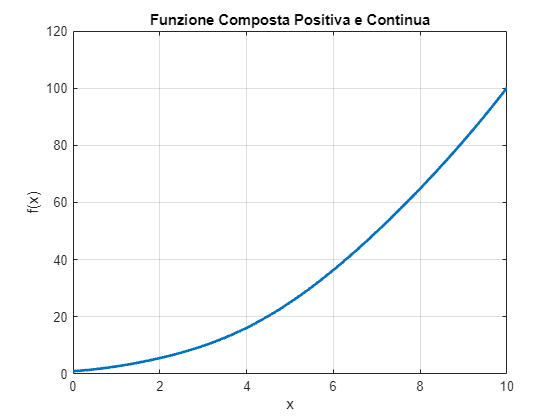

% Plot della funzione per verificarne la positività e la continuità
figure;
plot(x, y, 'LineWidth', 2);
xlabel('x');
ylabel('f(x)');
title('Funzione Composta Positiva e Continua');
grid on;


% Verificare la positività (Per sicurezza, manda questo messaggio di errore
% se nei punti successivi è diverso)
assert(all(y > 0), 'La funzione non è positiva su tutto l''intervallo.');

% Funzione per formula trapezoidale composita
function I = trapezoidal_composite(f, a, b, m)
    h = (b - a) / m;
    x = linspace(a, b, m+1);
    fx = f(x);
    I = h * (sum(fx) - (fx(1) + fx(end)) / 2);
end

% Funzione per formula di Simpson composita
function I = simpson_composite(f, a, b, m)
    if mod(m, 2) ~= 0
        error('m deve essere pari per la formula di Simpson');
    end
    h = (b - a) / m;
    x = linspace(a, b, m+1);
    fx = f(x);
    I = h / 3 * (fx(1) + fx(end) + 4 * sum(fx(2:2:end-1)) + 2 * sum(fx(3:2:end-2)));
end

% Valori di m (numero di sottointervalli) (4.3)
m_values = [2, 4, 8, 16, 32];

% Inizializzare vettori per memorizzare i risultati (4.3) (Sempre da
% inizializzare per evitare errori)
I_trapezoid = zeros(size(m_values));
I_simpson = zeros(size(m_values));
error_trapezoid = zeros(size(m_values));
error_simpson = zeros(size(m_values));

% Funzione per formula trapezoidale composita (Copiata e incollata, grazie)
trapezoidal_rule = @(f, a, b, m) trapezoidal_composite(f, a, b, m);

% Funzione per formula di Simpson composita, la formula più
% accurata ma lenta di approssimazione
simpson_rule = @(f, a, b, m) simpson_composite(f, a, b, m);

% Calcolare l'integrale e gli errori per ciascun valore di m
for i = 1:length(m_values)
    m = m_values(i);
    
    % Formula trapezoidale (m è il grado della di simpson, ovvero quante volte è composta per fare la sommatoria da i=1 o 2 a m, aumenta
    % l'accuratezza (l'errore diminuisce), ma anche i calcoli da fare)
    I_trapezoid(i) = trapezoidal_rule(f, a, b, m);
    error_trapezoid(i) = abs(I_trapezoid(i) - I_exact);
    
    % Formula di Simpson  Nota: il grado di errore deve essere pari. Ho
    % dovuto rivedermi meglio l'ARGOMENTO 6.1 per comprendere meglio
    if mod(m, 2) == 0
        I_simpson(i) = simpson_rule(f, a, b, m);
        error_simpson(i) = abs(I_simpson(i) - I_exact);
    else
        I_simpson(i) = NaN;
        error_simpson(i) = NaN;
    end
end

% Visualizzare i risultati
fprintf('Risultati usando la formula trapezoidale:\n');

Risultati usando la formula trapezoidale:


for i = 1:length(m_values)
    fprintf('m = %d: Integrale = %.10f, Errore = %.10e\n', m_values(i), I_trapezoid(i), error_trapezoid(i));
end

m = 2: Integrale = 378.0439315812, Errore = 3.7073857428e+01
m = 4: Integrale = 350.6728101051, Errore = 9.7027359523e+00
m = 8: Integrale = 343.4104322831, Errore = 2.4403581304e+00
m = 16: Integrale = 341.5809661901, Errore = 6.1089203735e-01
m = 32: Integrale = 341.1228457549, Errore = 1.5277160214e-01



fprintf('\nRisultati usando la formula di Simpson:\n'); % (Errore= 10^-m, secondo le slides)


Risultati usando la formula di Simpson:


for i = 1:length(m_values)
    if ~isnan(I_simpson(i))
        fprintf('m = %d: Integrale = %.10f, Errore = %.10e\n', m_values(i), I_simpson(i), error_simpson(i));
    else
        fprintf('m = %d: Formula di Simpson non applicabile\n', m_values(i));
    end
end

m = 2: Integrale = 335.4456666768, Errore = 5.5244074760e+00
m = 4: Integrale = 341.5491029464, Errore = 5.7902879361e-01
m = 8: Integrale = 340.9896396758, Errore = 1.9565523053e-02
m = 16: Integrale = 340.9711441591, Errore = 1.0700063369e-03
m = 32: Integrale = 340.9701389432, Errore = 6.4790404167e-05


 
% 4.4 Definire i nodi distinti non equispaziati nell'intervallo [1, 5]
x = [1.5, 2.7, 3.2, 4.8];

% Costruire il sistema lineare per determinare i pesi preconfezionando il
% metodo di Lagrange, praticamente una matrice di vondermonde trasposta (B'),
% come nell'ultima ora dell'ultima lezione, e al compito così l'ho fatta,
% ma stavolta la scrivo in modo lungo perché ho più di un'ora di tempo 
A = [1, 1, 1, 1; 
    x(1), x(2), x(3), x(4);
    x(1)^2, x(2)^2, x(3)^2, x(4)^2;
    x(1)^3, x(2)^3, x(3)^3, x(4)^3];
%b=I, non voglio fare confusione con le variabili precedenti
b = [4 - 0;
    4^2 / 2 - 0^2 / 2;
    4^3 / 3 - 0^3 / 3; 
    4^4 / 4 - 0^4 / 4]; % a=4 e b=0, b^k(=i+1)-a^k

% Risolvere il sistema lineare per ottenere i pesi (4.5)
w = A \ b;

% Calcolare l'integrale approssimato utilizzando la formula di quadratura
% (Non nell'esercizio del compito) Nota: di grado al più tre: è il caso
% standard
Q_f = w(1) * f(x(1)) + w(2) * f(x(2)) + w(3) * f(x(3)) + w(4) * f(x(4));

% Visualizzare i risultati (4.5)
fprintf('I nodi sono: x1 = %.2f, x2 = %.2f, x3 = %.2f, x4 = %.2f\n', x(1), x(2), x(3), x(4));

I nodi sono: x1 = 1.50, x2 = 2.70, x3 = 3.20, x4 = 4.80


fprintf('I pesi sono: w1 = %.6f, w2 = %.6f, w3 = %.6f, w4 = %.6f\n', w(1), w(2), w(3), w(4));

I pesi sono: w1 = 5.121014, w2 = -9.481481, w3 = 8.882353, w4 = -0.521886


fprintf('Il valore approssimato dell''integrale è: %.10f\n', Q_f);

Il valore approssimato dell'integrale è: 25.8785219933



% Confrontare con l'integrale esatto calcolato con l'integrale della
% quadratura
% (Dovrebbe essere poco diverso)
I_exact = integral(f, 0, 4, 'RelTol', tol, 'AbsTol', tol); % Ricorda: Da 0 a 4
fprintf('Il valore esatto dell''integrale calcolato con integral è: %.10f\n', I_exact);

Il valore esatto dell'integrale calcolato con integral è: 26.1042718932


fprintf('L''errore di approssimazione è: %.10e\n', abs(Q_f - I_exact));

L'errore di approssimazione è: 2.2574989986e-01


Scrivere una relazione che mostri tutto quanto richiesto nei punti precedenti. E' necessario che nella relazione tutti i risultati numerici siano commentati scrivendo esplicitamente a che cosa riferisce ogni risultato numerico e, quando richiesto, se tale risultato è quello atteso. Usare il `format long` per tutti i risultati. Anche tutti grafici devono essere commentati. La relazione deve essere un LIVE SCRIPT, estensione `.mlx`, creato usando il LIVE EDITOR di Matlab. Il file deve essere eseguito (RUN) nella modalità che inserisce risultati e gradici all'interno del testo (e NON sulla destra).

Il file `.mlx` che contiene la relazione (eseguita con un RUN)  **deve essere caricato, insieme con il file  **`DatiHW2**, `** entro e non oltre il 16 giugno 2024 , ore 23:59, sulla piattaforma TEAMS,**** Team del corso di Calcolo Numerico.** 

**Pena ****esclusione dalla prova** bisogna:

- indicare all'inizo della relazione: Cognome, Nome e numero di matricola;

- denominare il file nel seguente modo: **HW2_Cognome_Nome.mlx**;